clear all

### Problema 1

**Adelanto de fase**

Diseñe un compensador de adelanto de fase 𝐺𝐺𝐶𝐶 (𝑠𝑠) tal que, en lazo cerrado, el margen de fase sea

𝑃𝑀 ≈ 45° y el margen de ganancia sea 𝐺𝑀 > 8𝑑b. Considere una constante estática de error de

velocidad de 𝑐𝑣 = 4𝑠eg−1.

syms s Kc
syms w
G_s = 32/(s*(0.1*s + 1)*(s + 1))

$$G\_s = \frac{32}{s\,\left(\frac{s}{10}+1\right)\,\left(s+1\right)}$$

Pmd = 45;
Gmd = 8;
Cv = 4

Cv = 4

Paso 1: Obtener la ganancia Kc

Kc_val = solve(Cv == limit(s*G_s*Kc, s, 0), Kc)

$$Kc\_val = \frac{1}{8}$$

Kc_val = double(Kc_val);

Paso 2: Obtener Pm de G(s)*Kc

[Gm, Pm] = margin(sym2tf(G_s)*Kc_val)

Gm = 2.7500

Pm = 17.7051

Paso 3: Obtener la fase 

compTest = 14.4 % 5 - 12 grados

compTest = 14.4000


phim = deg2rad(Pmd-Pm+compTest)

phim = 0.7277

Paso 4: Obtener beta con phim

beta=(1-sin(phim))/(1+sin(phim))

beta = 0.2011

Paso 5: Obtener la frecuencia omega que cumpla con lo siguiente:

|G(wi)|^2 = beta

*Tenemos que sustituir s por wi y despejar w

L_s = Kc_val*G_s

$$L\_s = \frac{4}{s\,\left(\frac{s}{10}+1\right)\,\left(s+1\right)}$$

L_jw = subs(L_s, s, 1i*w)

$$L\_jw = -\frac{4\,\mathrm{i}}{w\,\left(1+w\,\mathrm{i}\right)\,\left(1+\frac{w\,\mathrm{i}}{10}\right)}$$

w_val = vpasolve(abs(L_jw)^2 == beta, w, [0 100])

$$w\_val = 2.8450385956512045205925051055919$$

w_val = double(w_val)

w_val = 2.8450

Paso 6: 

Calcular beta1 y beta2

beta1=sqrt(beta)*w_val

beta1 = 1.2758

beta2=w_val/sqrt(beta)

beta2 = 6.3446

Paso 7: Comprobar si se obtuvieron los requerimientos deseados calculando Gm y Pm de Gc(s)*G(s)

Gc_s=(Kc_val/beta)*tf([1 beta1],[1 beta2])

Gc =
 
  0.6216 s + 0.7931
  -----------------
      s + 6.345
 
Continuous-time transfer function.
Model Properties


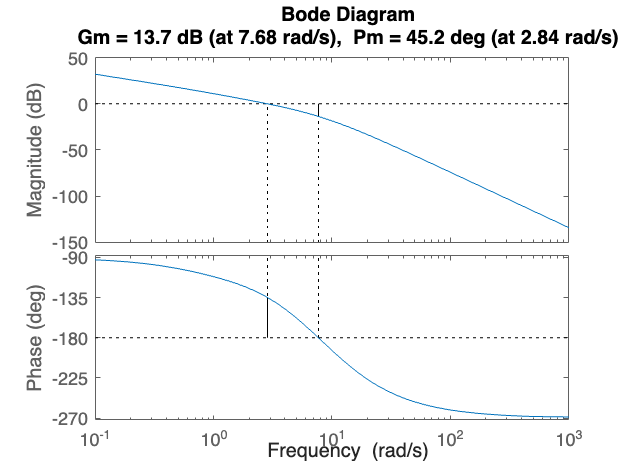

margin(Gc_s*sym2tf(G_s))

### Problema 2

**Atraso de fase**

Diseñe un compensador de atraso de fase 𝐺𝐶 (𝑠) tal que, en lazo cerrado, el margen de fase sea

𝑃𝑀 ≈ 50° y el margen de ganancia sea 𝐺𝑀 > 8𝑑b. Considere una constante estática de error de

posición de 𝑐p = 4𝑠eg.

syms s Kc
syms a omega
G_s = (2*s + 0.1)/(s^2+0.1*s+4)

$$G\_s = \frac{2\,s+\frac{1}{10}}{s^{2}+\frac{s}{10}+4}$$

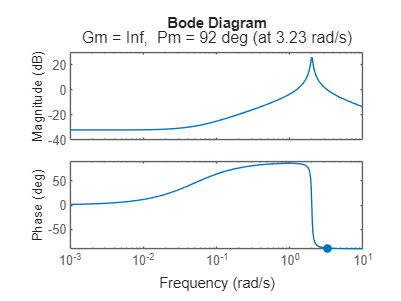

Pmd = 50;
Gmd = 8;
Cp = 4;
margin(sym2tf(G_s))

Paso 1: Obtener la ganancia Kc

Kc_val = solve(Cp == limit(G_s*Kc, s, 0), Kc)

$$Kc\_val = 160$$

Kc_val = double(Kc_val)

Kc_val = 160

Paso 2: Determinar la frecuencia (omega) de G(jw)*Kc tal que se cumpla el Pm deseado pero compensado

Paso 2.1 Obtener margen de fase compensado

compAt = 5; % 5 - 12 grados

Paso 2.2 obtener omega

AngleInterest=Pmd+compAt-180

AngleInterest = -125


[mag, phase, w] = bode(sym2tf(G_s)*Kc_val);
mag = squeeze(mag);
phase = squeeze(phase);
w = squeeze(w);


[~, idx] = min(abs(phase - AngleInterest));

omeg = w(idx)

omeg = 10

phase(idx);
mag(idx);

Paso 3 Obtener alpha con la ecuación |G(jw)*Kc|^2 = alfa^2

G_jw = subs(G_s, s, 1i*omeg);

alpha_val = sqrt(abs(G_jw)^2);
alpha_val = double(alpha_val)

alpha_val = 0.2083

Paso 4: Obtener alfa1 y alfa2 con: alfa1 = omega/10 y alfa2 = omega/(10*alfa)

alpha1=omeg/10

alpha1 = 1

alpha2=omeg/(10*alpha_val)

alpha2 = 4.8002


Gc_s=(Kc_val/alpha_val)*tf([1 alpha1],[1 alpha2])


Gc_s =
 
  768 s + 768
  -----------
    s + 4.8
 
Continuous-time transfer function.
Model Properties


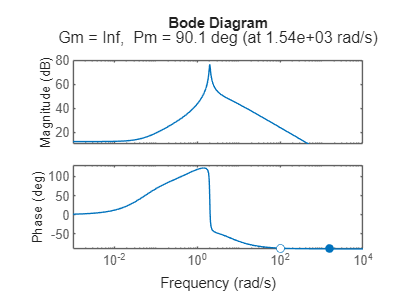


margin(Gc_s*sym2tf(G_s))